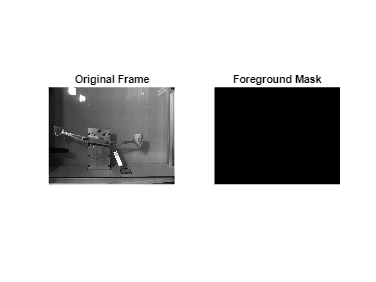

% frame0 = load("Imports\video1\Ballenwerper_sync_380fps_006.npychunk_0.mat");
% frame1 = load("Imports\video1\Ballenwerper_sync_380fps_006.npychunk_1.mat");
% frame2 = load("Imports\video1\Ballenwerper_sync_380fps_006.npychunk_2.mat");
% frame3 = load("Imports\video1\Ballenwerper_sync_380fps_006.npychunk_3.mat");
% frame4 = load("Imports\video1\Ballenwerper_sync_380fps_006.npychunk_4.mat");
% frame5 = load("Imports\video1\Ballenwerper_sync_380fps_006.npychunk_5.mat");
% frame6 = load("Imports\video1\Ballenwerper_sync_380fps_006.npychunk_6.mat");
% frame7 = load("Imports\video1\Ballenwerper_sync_380fps_006.npychunk_7.mat");
% frame8 = load("Imports\video1\Ballenwerper_sync_380fps_006.npychunk_8.mat");
% frame9 = load("Imports\video1\Ballenwerper_sync_380fps_006.npychunk_9.mat");

%video = cat(1, frame0.video_data, frame1.video_data, frame2.video_data, frame3.video_data, frame4.video_data, frame5.video_data, frame6.video_data, frame7.video_data);
 

numFrames = size(video, 1); % Number of frames in the video
height = size(video, 2);    % Height of each frame
width = size(video, 3);     % Width of each frame

% Foreground Detector Initialization
foregroundDetector = vision.ForegroundDetector(...
    'NumTrainingFrames', 50, ...      % Number of frames used to learn initial background
    'InitialVariance', 30*30, ...     % Initial variance of the background model
    'MinimumBackgroundRatio', 0.7, ...% Controls how quickly background adapts
    'LearningRate', 0.005);           % Controls adaptation speed to changes

% Initialize Output
foregroundMasks = false(numFrames, height, width); % To store the binary masks

% Process Each Frame
for k = 1:numFrames
    % Extract the k-th frame
    currentFrame = squeeze(video(k, :, :)); % Extract height x width for frame k
    
    % Ensure the frame is in double precision for processing
    currentFrame = im2double(currentFrame);
    
    % Compute Foreground Mask
    foregroundMask = step(foregroundDetector, currentFrame);
    
    % Clean the Mask (optional)
    foregroundMask = imopen(foregroundMask, strel('disk', 3)); % Remove noise
    foregroundMask = imclose(foregroundMask, strel('disk', 3)); % Fill gaps
    foregroundMask = bwareaopen(foregroundMask, 50); % Remove small objects
    
    % Save the mask
    foregroundMasks(k, :, :) = foregroundMask;
    
    % Optional: Display results (comment out for batch processing)
    figure(1);
    subplot(1, 2, 1); imshow(currentFrame, []); title('Original Frame');
    subplot(1, 2, 2); imshow(foregroundMask, []); title('Foreground Mask');
    drawnow;
end


% Save or further process the foreground masks as needed
disp('Foreground detection completed.');
